# Example 3: double horizontal plot

In this case a similar plot to the one in Example 2 is created; however the selected orientation is 'horizontal'; which can be specified or left blank, since it's the default setting.

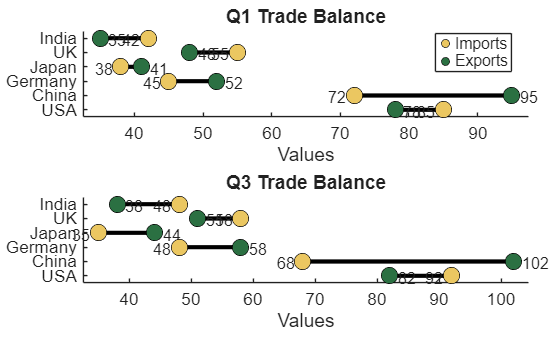

% Quarterly trade data for 6 countries (in billions USD)
countries = {'USA', 'China', 'Germany', 'Japan', 'UK', 'India'};

q1_imports = [85, 72, 45, 38, 55, 42];
q1_exports = [78, 95, 52, 41, 48, 35];  

q3_imports = [92, 68, 48, 35, 58, 48];
q3_exports = [82, 102, 58, 44, 51, 38];  

tradeData = table(q1_imports', q1_exports', q3_imports', q3_exports','VariableNames', ...
    {'Q1_Imports', 'Q1_Exports', 'Q3_Imports', 'Q3_Exports'}, 'RowNames', countries);

figure;
dumbbellPlot(tradeData,'Q1_Imports', 'Q1_Exports', 'Q3_Imports', 'Q3_Exports', ...
    'plotType','double','orientation','horizontal', 'labelX1', 'Imports','labelX2', ...
    'Exports','Title', {'Q1 Trade Balance', 'Q3 Trade Balance'});